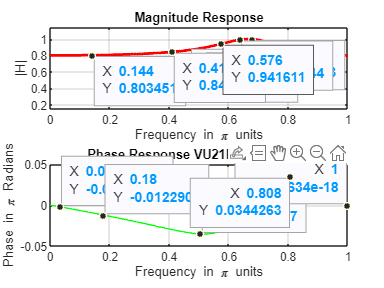

% Take user inputs for filter coefficients
b = input('Enter the numerator coefficients [b0, b1, b2, ...]: ');
a = input('Enter the denominator coefficients [a0, a1, a2, ...]: ');

m = 0:length(b)-1;
l = 0:length(a)-1;
K = 500;
k = 0:1:K;
w = pi*k/K;

num = b * exp(-1j * m' * w);
den = a * exp(-1j * l' * w);
H = num ./ den;
magH = abs(H);
angH = angle(H);

subplot(2, 1, 1);
plot(w/pi, magH, 'LineWidth', 2, 'Color', 'red');
grid on;
axis([0, 1, 0, 1]);
xlabel('Frequency in \pi units');
ylabel('|H|');
title('Magnitude Response');

subplot(2, 1, 2);
plot(w/pi, angH/pi, 'LineWidth', 1, 'Color', 'green');
grid on;
xlabel('Frequency in \pi units');
ylabel('Phase in \pi Radians');
title('Phase Response VU21EECE0100037');